# **Engineering Mathematics CA1**

## Mohammad Amanlou - 810100084

#### Example 1: 

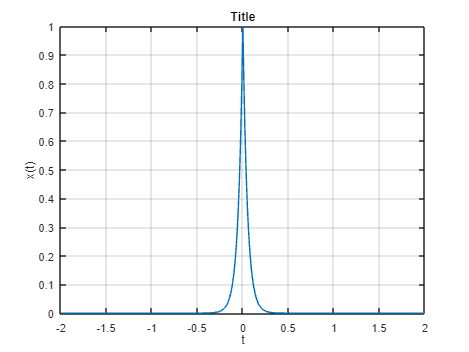

%Sample plotting
fs = 100;
t = -30:1/fs:30;
x = exp(-20.*abs(t));
plot(t, x);
xlabel('t')
ylabel('x(t)')
xlim([-2 2])
ylim([0 1])
title('Title')
grid on

### **Part 1:  Familiarity with MATLAB**

#### Question1.1: cot ( πt 4 ) sin ( πt 8 ) 

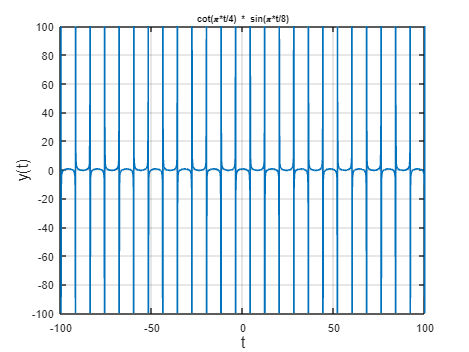

% Sample rate and time vector
fs = 10000;  % Sampling frequency
t = -100:1/fs:100;  % Time vector

% Function definition
y = cot(pi * t / 4) .* sin(pi * t / 8);

% Plotting the function
figure;
plot(t, y, 'LineWidth', 1.5);
xlabel('t', 'FontSize', 14);
ylabel('y(t)', 'FontSize', 14);
title('cot(\pi*t/4) * sin(\pi*t/8)', 'FontSize', 8);
grid on;
xlim([-100 100]);
ylim([-100 100]);

#### Question1.2: Sgn(1/(t^2))

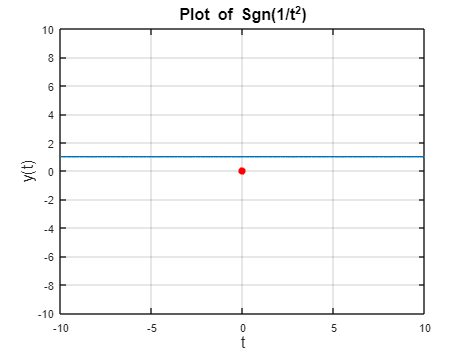

fs = 10000;  % Sampling frequency
t = -10:1/fs:10;  % Time vector

% Function definition
y = sign(1 ./ (t .^ 2));

% Plotting the function
figure;
plot(t, y, 'LineWidth', 1.5);
xlabel('t', 'FontSize', 14);
ylabel('y(t)', 'FontSize', 14);
title('Plot of Sgn(1/t^2)', 'FontSize', 14);
grid on;
xlim([-10 10]);  % Adjust x-axis limits
ylim([-10 10]);  % Adjust y-axis limits

% Handle the point at t = 0 where the function is undefined
hold on;
plot(0, 0, 'ro', 'MarkerFaceColor', 'r');  % Mark the undefined point

#### Question1.3: 

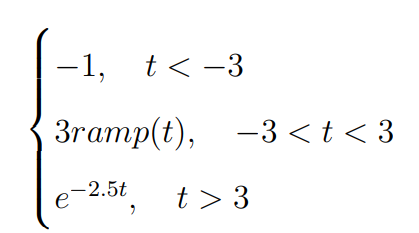

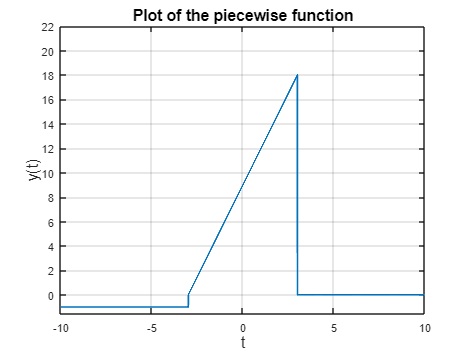

% Define the time vector
fs = 1000;  % Sampling frequency
t = -10:1/fs:10;  % Time vector

% Initialize the function
y = zeros(size(t));

% Define the piecewise function
y(t < -3) = -1;
y(t >= -3 & t <= 3) = 3 * (t(t >= -3 & t <= 3) + 3);
y(t > 3) = exp(-2.5 * t(t > 3));

% Plot the function
figure;
plot(t, y, 'LineWidth', 1.5);
xlabel('t', 'FontSize', 14);
ylabel('y(t)', 'FontSize', 14);
title('Plot of the piecewise function', 'FontSize', 14);
grid on;
xlim([-10 10]);  % Adjust x-axis limits
ylim([-1.5 22]);  % Adjust y-axis limits

### Part2: Fourier Series

#### Question 2.2: Calculate the Fourier series of a certain 

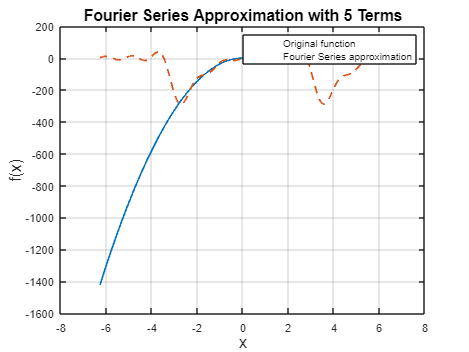

Num = 10;   % تعداد جملات سری فوریه
P = 2 * pi  ; % تناوب
alpha = 1;  % توان چند جمله ای
Nshow = 5;  % تعداد جملات سری فوریه جهت نمایش
beta = 2;
figure;
fourier_series_ln(Num, P, alpha, beta, Nshow) 

#### Question2.3: Draw the Fourier series and compare with the main function

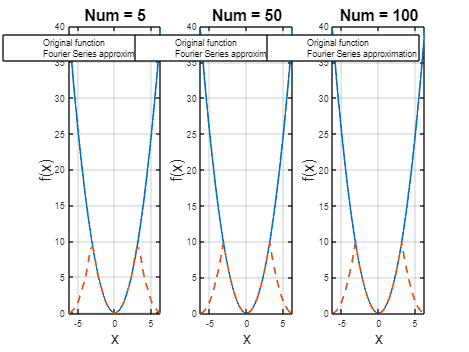

P = 2 * pi; % Period
alpha = 2; % Exponent of the polynomial
Nshow = 50; % Number of terms to show in the Fourier series approximation
Num_values = [5, 50, 100]; % Different values for Num

% Plot the x^2 function with different values for Num
figure;
for i = 1:length(Num_values)
    Num = Num_values(i);
    subplot(1, length(Num_values), i);
    fourier_series(Num, P, alpha, Nshow);
    title(['Num = ', num2str(Num)]);
end

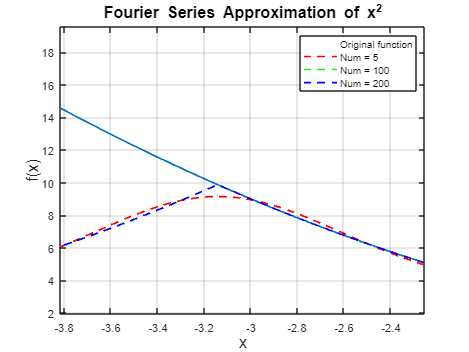

fourier_series_plot([5, 100, 200], 2 * pi, 2);

#### Question2.4: Calculate the total limit and match the results

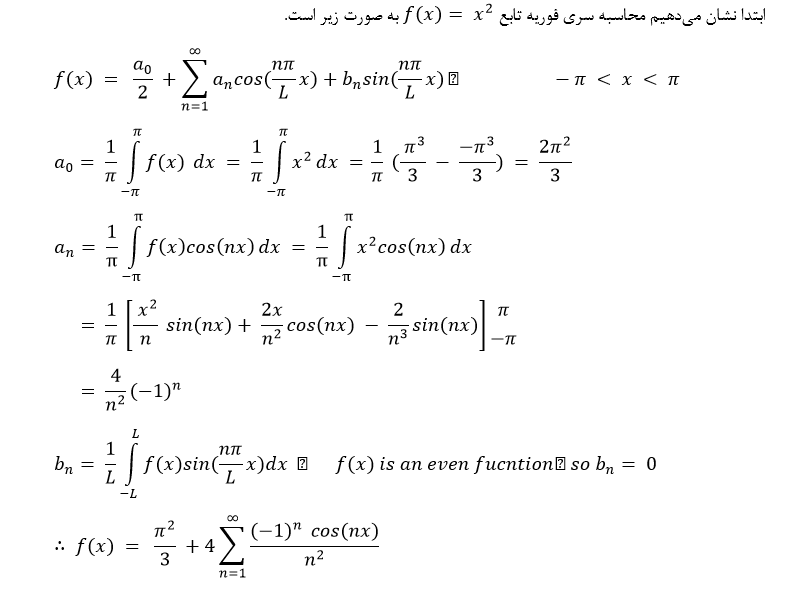

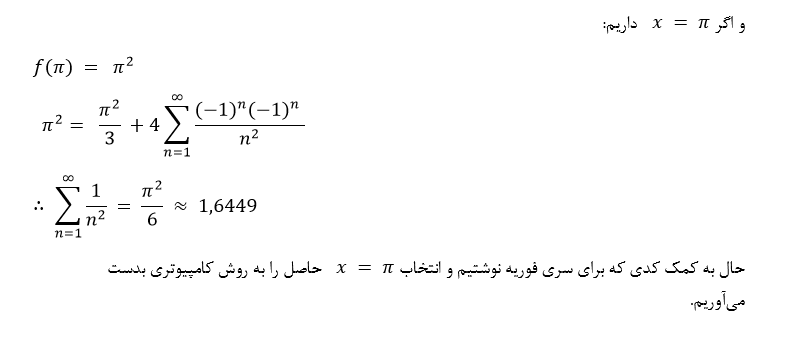

fprintf('pi^2 = %f \n',pi^2 / 6);

pi^2 = 1.644934 


disp('Cheking diffrence between two Values')

Cheking diffrence between two Values


a=(pi^2)/6;
sum=0;
i=1;
%% Solution with Numerical calculation

    while(a-sum)>(10^(-8))
        sum=sum+(1/i^2);
        i=i+1;
    end
    disp('Equation is true')

Equation is true


.

% تعداد جمله های سری فوریه
N = 1000;
x = pi;
f_approx = pi^2 / 3;
f_real = pi^2 ;
for n = 1:N
    f_approx = f_approx + 4 * (((-1)^n) / (n^2)) * cos(n*x);
end


fprintf('f real is %f \n' , f_real);

f real is 9.869604 


fprintf('f approx is %f \n' , f_approx);

f approx is 9.865606 


#### Question2.5: Harmonic analysis in Fourier series

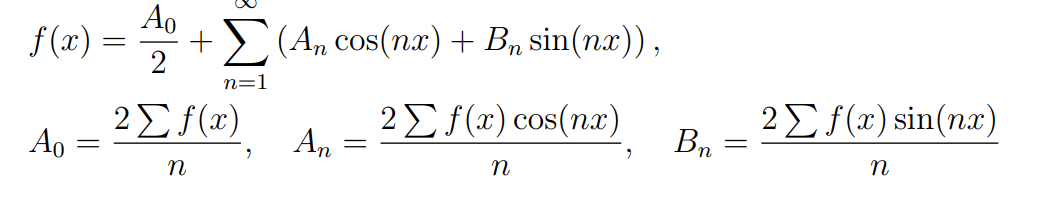

#### Question2.5.1: Simulation of harmonic analysis

f(x) = 1.3857 + -0.0286 cos(1x) + 0.1485 sin(1x) + 0.2000 cos(2x) + -0.0495 sin(2x) + 0.3143 cos(3x) + -0.0000 sin(3x) + 0.2000 cos(4x) + 0.0495 sin(4x)


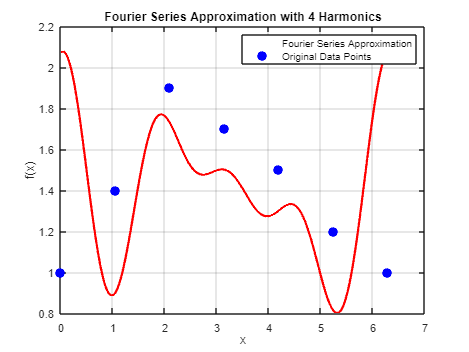

figure;
x = [0, pi/3, 2*pi/3, pi, 4*pi/3, 5*pi/3, 2*pi];
fx = [1, 1.4, 1.9, 1.7, 1.5, 1.2, 1];
n_harmonics = 4;

% فراخوانی تابع
hfourier_series(x, fx, n_harmonics);

### Part3: Fourier transform

#### Question3.1: Sampling frequency

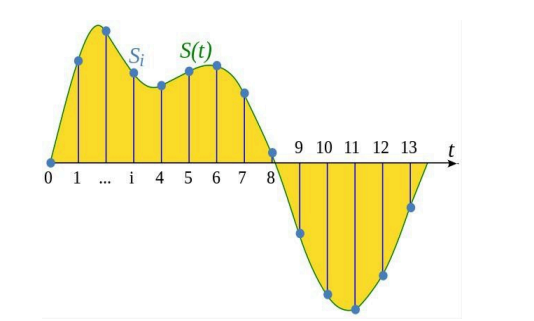 

#### Part 3.2: Investigating the time and frequency domains of multiple functions:

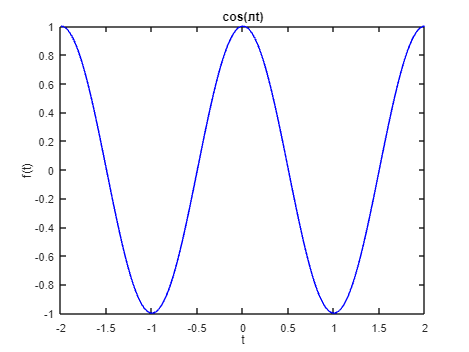

fs = 1000;
t = linspace(-2,2,fs);
y = cos(pi*t);
plot(t,y,"blue");
title("cos(лt)");
ylabel("f(t)");
xlabel("t");

Now we want to calculate the Fourier transform of this function with the help of "fft" and fftshift commands. Using the fft command, we calculate the Fourier transform of a discrete function, and then using the fftshift command, we bring it to the beginning and the center becomes zero. In fact, the zero frequency component of the discrete Fourier transform shifts to the center of the spectrum to show the shape of the Fourier transform diagram more clearly.

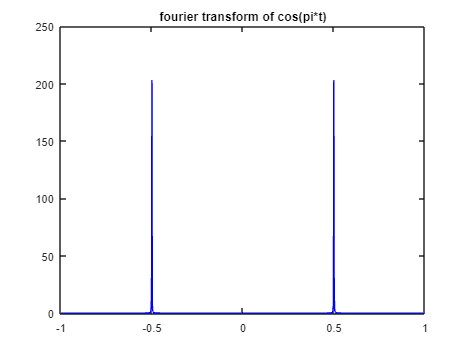

fs = 1000;               
t = (0:fs)/2;
g = cos(pi*t);
n = length(g);
x = fft(g);
f = (0:n-1)/10;
power = abs(x).^2/n;
y = fftshift(x);
fshift = (-500:500)/500;
powershift = abs(y).^2/n;
plot(fshift,powershift,"blue")
title('fourier transform of cos(pi*t)')

Now we want to theoretically calculate the Fourier transform of the function f(x)=cos(πt).

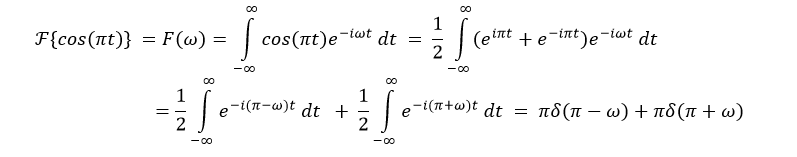 

Now we repeat all the above steps for the function f(x)=δ(x).

First, we draw this function in the time domain in two periodic periods. f_s=1000 is considered for drawing.

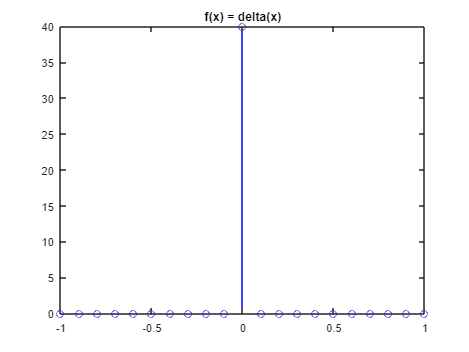

x = -1:0.1:1;
sigma = 0.01; 
y = exp(-x.^2 / (2 * sigma^2)) / (sigma * sqrt(2 * pi));

stem(x, y, "blue");
title("f(x) = delta(x)");

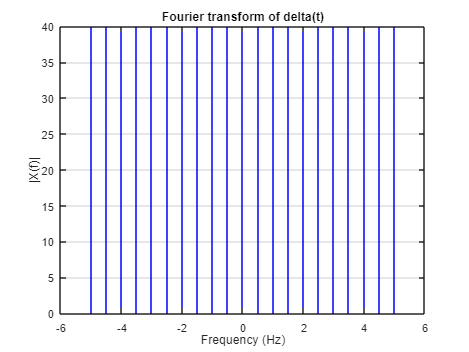

Xs = abs(fftshift(fft(y)));
fs = 1 / (x(2) - x(1)); 
l = length(x);
figure;
stem(linspace(-fs/2, fs/2, l), abs(Xs), "blue");
grid on;
xlabel("Frequency (Hz)");
ylabel("|X(f)|");
title("Fourier transform of delta(t)");

We calculate the Fourier transform solution of this function theoretically.

 

Now we repeat all the above steps for the function f(x)=1. 

First, we draw this function in the time domain in two periodic periods. f_s=1000 is considered for drawing.

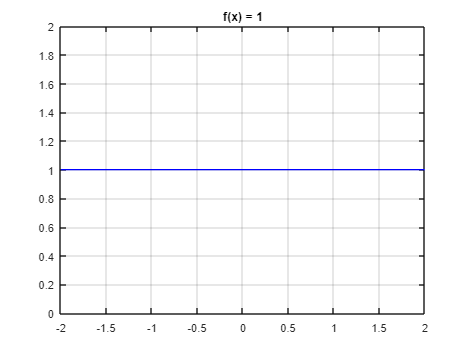

l = 2;
fs =  1000;
T = 1/fs;
t = -l:T:l;
xt = ones(size(t));
figure
plot(t,xt,"blue")
grid on
title('f(x) = 1')

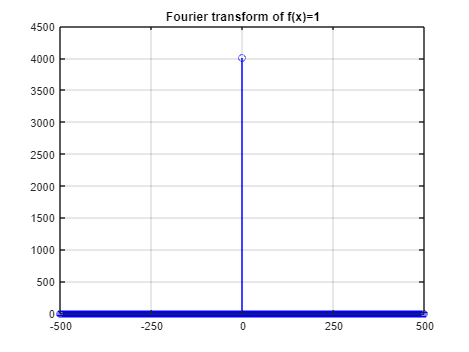

Xs = abs(fftshift(fft(xt)));
figure
stem(t,abs(Xs),"blue")
grid on
xticks(-l:1:l)
xticklabels(linspace(-fs/2,fs/2, numel(-l:1:l)))
title("Fourier transform of f(x)=1")

Now we calculate the Fourier transform of this function theoretically.

 

### Part3.3: Music:

In this section, we will work with a music file. First, we open the desired music file using MATLAB commands and listen to it. We also measure the sampling frequency with the disp command.

[y,Fs]=audioread("ABITW.mp3");
sound(y,Fs);
disp(Fs);

       44100



By doubling the frequency, the sound becomes lower. Also, the speed of playing music is doubled and its time is halved.

[y,Fs]=audioread("ABITW.mp3");
audiowrite("ABITW_Fast.wav",y,2*Fs);
[y,Fs]=audioread("ABITW_Fast.wav");
sound(y,Fs);
disp(Fs);

       88200



By halving the frequency, the sound becomes louder. Also, the speed of playing music is doubled and its time is doubled.

[y,Fs]=audioread("ABITW.mp3");
audiowrite("ABITW_Slow.wav",y,0.5*Fs);
[y,Fs]=audioread("ABITW_Slow.wav");
sound(y,Fs);
disp(Fs);

       22050



#### Question2.1: Calculation of Fourier series & Other functions of Part2

function f_fourier = fourier_series(Num, P, alpha, Nshow)
    % Num: Number of terms in the Fourier series
    % P: Period
    % alpha: Exponent of the polynomial
    % Nshow: Number of terms to show in the Fourier series approximation
    
    % Define the original function
    T = P; % Period
    f = @(x) x.^alpha ; % Original function
    
    % Calculate the Fourier coefficients
    a0 = (2/T) * integral(f, -T/2, T/2);
    a = zeros(1, Num);
    b = zeros(1, Num);
    for n = 1:Num
        a(n) = (2/T) * integral(@(x) f(x) .* cos(2 * pi * n * x / T), -T/2, T/2);
        b(n) = (2/T) * integral(@(x) f(x) .* sin(2 * pi * n * x / T), -T/2, T/2);
    end

    % Compute the Fourier series approximation
    f_fourier = @(x_real) a0 / 2;
    for n = 1:Num
        f_fourier = @(x_real) f_fourier(x_real) + a(n) * cos(2 * pi * n * x_real / T) + b(n) * sin(2 * pi * n * x_real / T);
    end

    % Plot the original function and the Fourier series approximation
    x_range = linspace(-T, T, 1000);
    f_original = f(x_range);
    f_fourier_approx = f_fourier(x_range);
    plot(x_range, f_original, 'LineWidth', 1.5);
    hold on;
    plot(x_range, f_fourier_approx, '--', 'LineWidth', 1.5);
    hold off;
    xlabel('x', 'FontSize', 14);
    ylabel('f(x)', 'FontSize', 14);
    legend('Original function', 'Fourier Series approximation');
    title(['Fourier Series Approximation with ', num2str(Nshow), ' Terms'], 'FontSize', 14);
    grid on;
end

function fourier_series_plot(Num_list, P, alpha)
    % Num_list: List of numbers of terms in the Fourier series
    % P: Period
    % alpha: Exponent of the polynomial

    % Define the original function
    T = P; % Period
    f = @(x) x.^alpha ; % Original function

    % Precompute the Fourier coefficients for the largest Num in Num_list
    max_Num = max(Num_list);
    a0 = (2/T) * integral(f, -T/2, T/2);
    a = zeros(1, max_Num);
    b = zeros(1, max_Num);
    for n = 1:max_Num
        a(n) = (2/T) * integral(@(x) f(x) .* cos(2 * pi * n * x / T), -T/2, T/2);
        b(n) = (2/T) * integral(@(x) f(x) .* sin(2 * pi * n * x / T), -T/2, T/2);
    end

    % Plot the original function
    x_range = linspace(-20, 20, 1000);
    f_original = f(x_range);
    plot(x_range, f_original, 'LineWidth', 1.5);
    hold on;

    % Compute and plot the Fourier series approximations for each Num in Num_list
    colors = ['r', 'g', 'b', 'c', 'm', 'y', 'k']; % Colors for the approximations
    for k = 1:length(Num_list)
        Num = Num_list(k);
        f_fourier = @(x_real) a0 / 2;
        for n = 1:Num
            f_fourier = @(x_real) f_fourier(x_real) + a(n) * cos(2 * pi * n * x_real / T) + b(n) * sin(2 * pi * n * x_real / T);
        end
        f_fourier_approx = f_fourier(x_range);
        plot(x_range, f_fourier_approx, '--', 'Color', colors(mod(k-1, length(colors)) + 1), 'LineWidth', 1.5);
    end

    hold off;
    xlabel('x', 'FontSize', 14);
    ylabel('f(x)', 'FontSize', 14);
    legend_entries = [{'Original function'}, arrayfun(@(n) ['Num = ', num2str(n)], Num_list, 'UniformOutput', false)];
    legend(legend_entries{:});
    title(['Fourier Series Approximation of x^', num2str(alpha)], 'FontSize', 14);
    xlim([-20 20]); % Set x-axis limit to -20 to 20
    grid on;
end



function fourier_series_ln(Num, P, alpha, beta, Nshow)
    % Num: Number of terms in the Fourier series
    % P: Period
    % a: Constant for ln
    % beta: Exponent of x
    % Nshow: Number of terms to show in the Fourier series approximation
    
    % Define the original function
    T = P; % Period
    f = @(x) (x.^beta) .* log(max(alpha*x, eps)); % Original function with a condition to ensure positive input
    
    % Calculate the Fourier coefficients
    a0 = real((2/T) * integral(f, -T/2, T/2));
    a_coeffs = zeros(1, Num);
    b_coeffs = zeros(1, Num);
    for n = 1:Num
        a_coeffs(n) = real((2/T) * integral(@(x) f(x) .* cos(2 * pi * n * x / T), -T/2, T/2));
        b_coeffs(n) = real((2/T) * integral(@(x) f(x) .* sin(2 * pi * n * x / T), -T/2, T/2));
    end

    % Compute the Fourier series approximation
    f_fourier = @(x_real) real(a0 / 2);
    for n = 1:Nshow
        f_fourier = @(x_real) f_fourier(x_real) + real(a_coeffs(n) * cos(2 * pi * n * x_real / T) + b_coeffs(n) * sin(2 * pi * n * x_real / T));
    end

    % Plot the original function and the Fourier series approximation
    x_range = linspace(-T, T, 1000);
    f_original = f(x_range);
    f_fourier_approx = f_fourier(x_range);
    plot(x_range, f_original, 'LineWidth', 1.5);
    hold on;
    plot(x_range, f_fourier_approx, '--', 'LineWidth', 1.5);
    hold off;
    xlabel('x', 'FontSize', 14);
    ylabel('f(x)', 'FontSize', 14);
    legend('Original function', 'Fourier Series approximation');
    title(['Fourier Series Approximation with ', num2str(Nshow), ' Terms'], 'FontSize', 14);
    grid on;
end

function hfourier_series(x, fx, n_harmonics)
    % تعداد نقاط
    N = length(x);
    
    % محاسبه a0
    a0 = (2/N) * sum(fx);
    
    % مقادیر a_n و b_n
    a = zeros(n_harmonics, 1);
    b = zeros(n_harmonics, 1);
    
    for n = 1:n_harmonics
        a(n) = (2/N) * sum(fx .* cos(n * x));
        b(n) = (2/N) * sum(fx .* sin(n * x));
    end
    
    % نمایش سری فوریه
    fprintf('f(x) = %.4f', a0/2);
    for n = 1:n_harmonics
        fprintf(' + %.4f cos(%dx)', a(n), n);
        fprintf(' + %.4f sin(%dx)', b(n), n);
    end
    fprintf('\n');
    
    % رسم سری فوریه
    x_plot = linspace(0, 2*pi, 1000);
    f_approx = a0 / 2;
    for n = 1:n_harmonics
        f_approx = f_approx + a(n) * cos(n * x_plot) + b(n) * sin(n * x_plot);
    end
    
    figure;
    plot(x_plot, f_approx, 'r', 'LineWidth', 2);
    hold on;
    plot(x, fx, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
    xlabel('x');
    ylabel('f(x)');
    title(sprintf('Fourier Series Approximation with %d Harmonics', n_harmonics));
    legend('Fourier Series Approximation', 'Original Data Points');
    grid on;
end
